## `Whiplash Gradient Descent Algorithm`

This code and by extension the Whiplash Gradient Descent Algorithm is developed as a part of research coursework for undergraduate engineering for the course ENGN 4200 of the degree AENGI, Honours Project of The Australian National University, Canberra.

Project Supervisor:  **Prof. Dr. Ian R Petersen, FAA . **

Author: **Mr. Subhransu Sekhar Bhattacharjee, (Rudra) U7143478**

The Whiplash Method is a hybrid technique which are operational for all types of stiff methods. Here we have tried to optimise the Rosenbrock Banana Function, known for its ill condition and its global minima at (1,1). The Whiplash Method outperforms the Nesterov Accelerated Gradient Method as well as Adaptive Momentum Methods by exponenetial time rates for this problem. The discretisation used is the semi-implicit or simplectic Euler method. 

## Initialisation

clear
clc
close all
syms x y
t = 10^-9;
K = 50000000;
x_init1 = -120;
y_init1 = 200;
tic
[A, B] = WGD(x_init1,y_init1,K,t);
toc

Elapsed time is 2.029195 seconds.


fprintf('x* = %d', A(K-1,1))

x* = 1.000000e+00

fprintf('y* = %d', A(K-1,2))

y* = 1.000000e+00

## **Graphical Results**

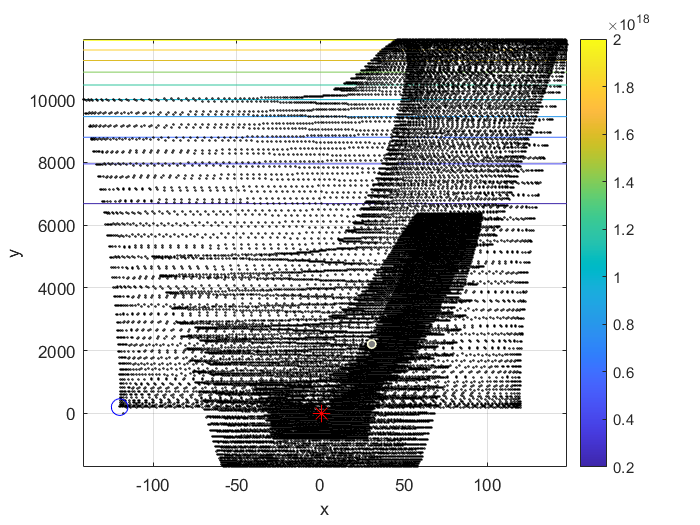

f = (1-x)^2+100*(x-y^2)^2;
title(' Initial condition: (5,5)')
fcontour(f,'fill','off','MeshDensity',500)
grid on
xlabel('x')
ylabel('y')
hold on
x = A(:,1);
y = A(:,2);
scatter(x,y,1,'black','o')
scatter(x_init1,y_init1,100,'blue','O')
scatter(A(K-1,1),A(K-1,2),100,'red','*')
colorbar
hold off

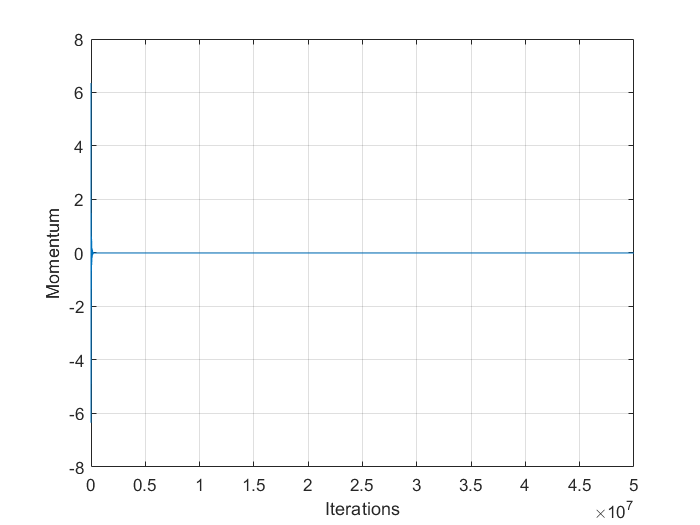

ax = gca;
t = B(:,1);
plot(t)
grid on
xlabel('Iterations')
ylabel('Momentum')

## WGD

function [A,B] = WGD(x_init,y_init,K,t)
k = 1;
x_k0 = x_init;
y_k0 = y_init;
x_k1 = x_init - t * grad_f_x(x_init,y_init);
y_k1 = y_init - t * grad_f_y(x_init,y_init);
A = zeros(K-1,2);
B = zeros(K-1,1);
while (k < K)
beta_x = sqrt(t)+ k*t*((x_k1 - x_k0)'*(x_k1 - x_k0));
x_k2 = x_k1 +(1- beta_x)*(x_k1 - x_k0) - t*grad_f_x(x_k1,y_k1);
B(k) = (x_k1 - x_k0);
A(k,1)= x_k2 ;
k =k + 1;
x_k0 = x_k1;
x_k1 = x_k2;
beta_y = sqrt(t)+ k*t*((y_k1 - y_k0)'*(y_k1 - y_k0));
y_k2 = y_k1 +(1- beta_y)*(y_k1 - y_k0) - t*grad_f_y(x_k1,y_k1);
A(k,2)= y_k2 ;
y_k0 = y_k1;
y_k1 = y_k2;
end
end

## Gradients

function g1 = grad_f_x(x,y)
 g1 = -400*(y - x^2)*x - 2*(1 - x);          
end
function g2 = grad_f_y(x,y)
 g2 = 200*(y - x^2);
end